# Varmelegeme målinger

T = readtable("varmelegeme_maalinger.xlsx");

## I sekunder

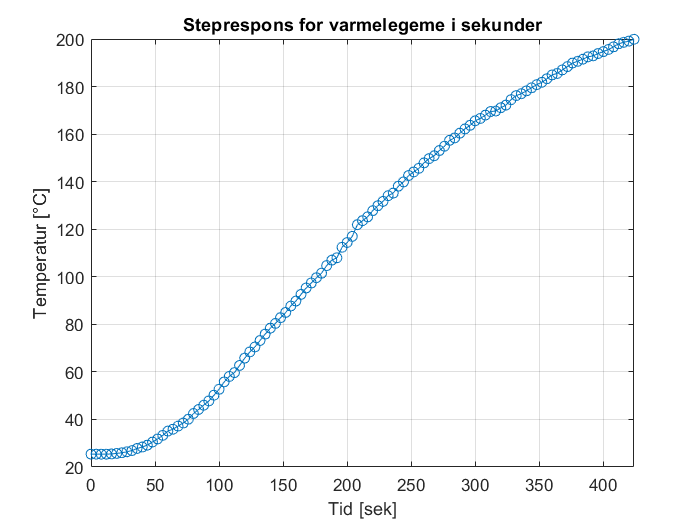

plot(T.Tid,T.Temperatur,'-o')
xlim([0,424]);
title('Steprespons for varmelegeme i sekunder');
xlabel('Tid [sek]');
ylabel('Temperatur [°C]');
grid on;

## I minutter

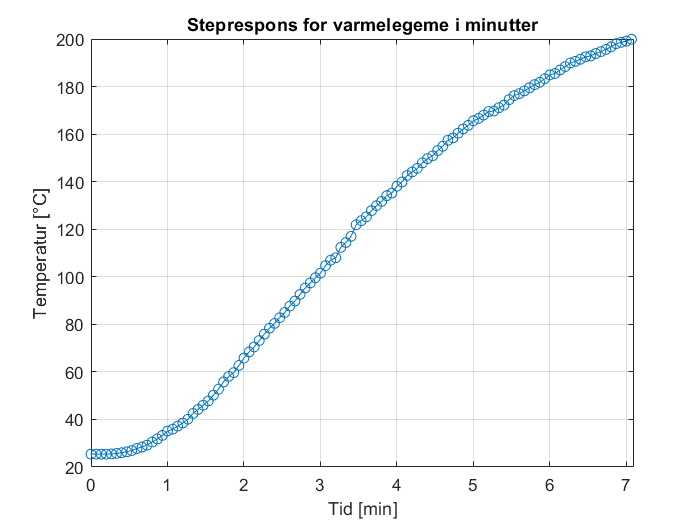

x = T.Tid./60;
plot(x,T.Temperatur,'-o')
xlim([0,7.1]);
title('Steprespons for varmelegeme i minutter');
xlabel('Tid [min]');
ylabel('Temperatur [°C]');
grid on;

## Steady-State

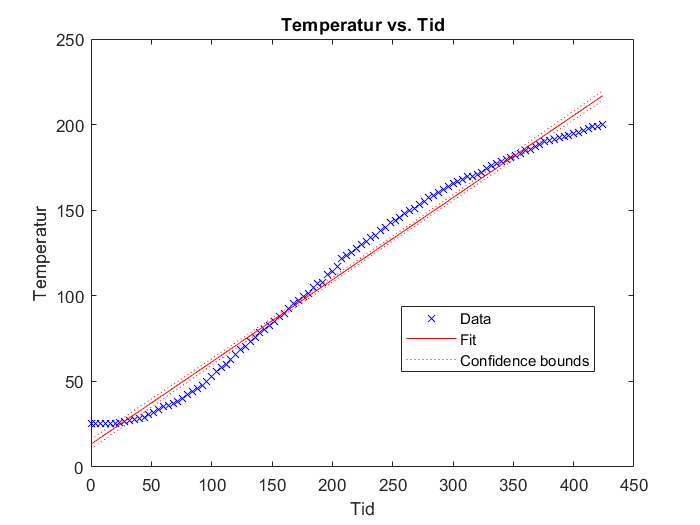

mdl = fitlm(T,"interactions");
plot(mdl);